clear
%% import the data if already converted to ANA
dir= 'E:\PhD\Adamantane_data\data\ascii_conv_data\Ada_PEPICO_hv287p61eV_ke260_0001_ascii\Ada_PEPICO_hv287p61eV_ke260_0001_ana';
raw_data = IO.import_raw(dir);
addpath('E:\PhD\Adamantane_data\mdata')
mdata = md_all();
data            = macro.filter(raw_data, mdata); %define the multiplicity of events
data_corrected = macro.correct(data, mdata);

Log: Detector image translation correction performed on det1
Log: Detector image rotation correction performed on det1
Log: Radial angle-dependent correction performed on det1
Log: Detector image translation correction performed on det2
Log: Detector image rotation correction performed on det2
Log: delta TOF correction performed on det2


data_converted = macro.convert(data_corrected, mdata);

Log: R, theta conversion performed on det1


data_out = struct with fields:
    e: [1×1 struct]
    h: [1×1 struct]


Log: Kinetic energy release conversion performed on det1
Log: m2q conversion performed on det2
Log: mass-to-charge (m2q) labeling performed on det2
Log: momentum conversion performed on det2
Log: Kinetic energy release conversion performed on det2
Log: R, theta conversion performed on det2
Log: angle p1 correlation calculated for C2


## Get data stats

[data_stats] =get_data_stats(data_converted);

The Scaling factor is 0.48224


## Plot AES

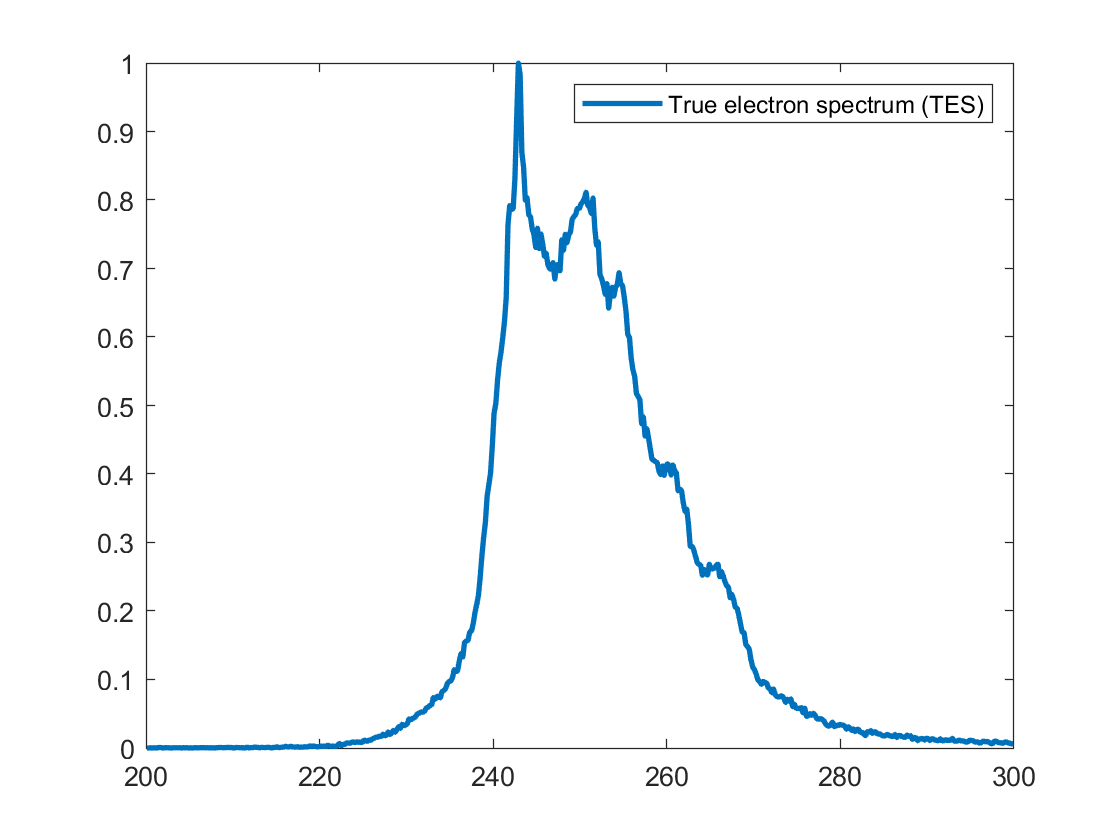

[centres, electron_KE] = get_AES(data_converted, data_stats);

## Plot PEPICO

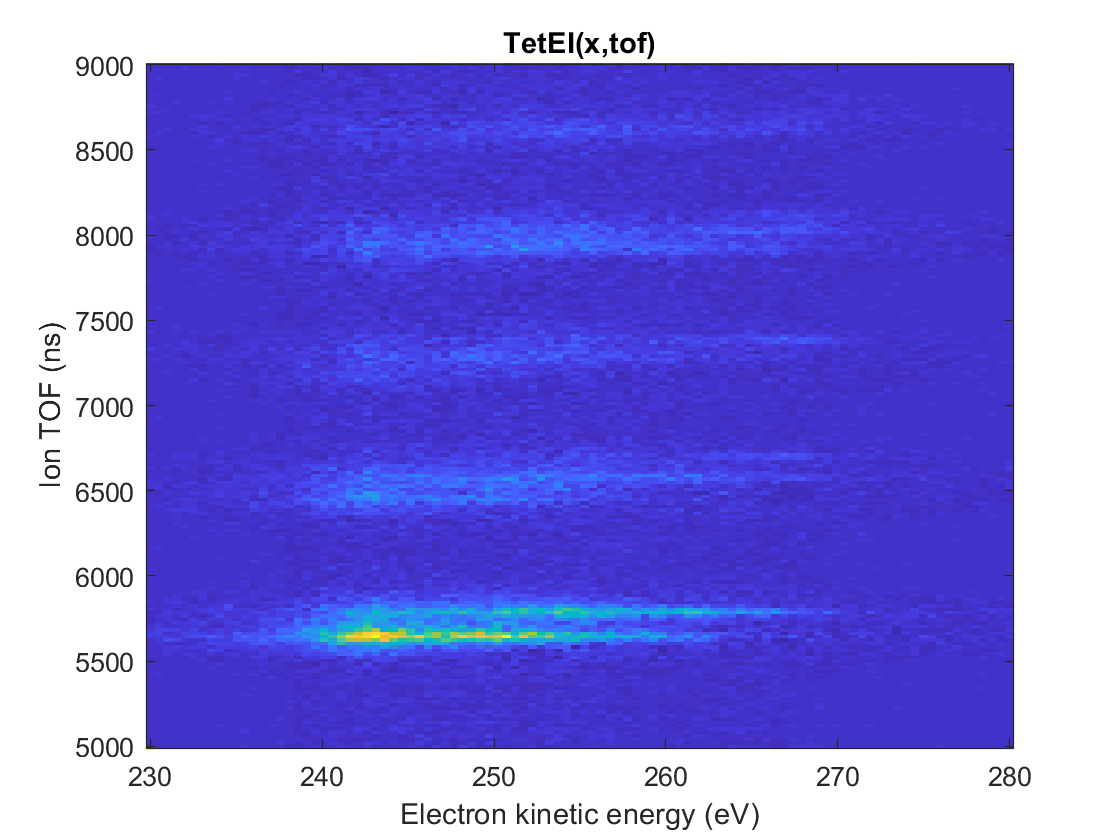


tof_range =[5000 ; 9000];

 [TetEI_x_tof,Xcenters,Ycenters] = plot_pepico(data_converted, data_stats,tof_range);

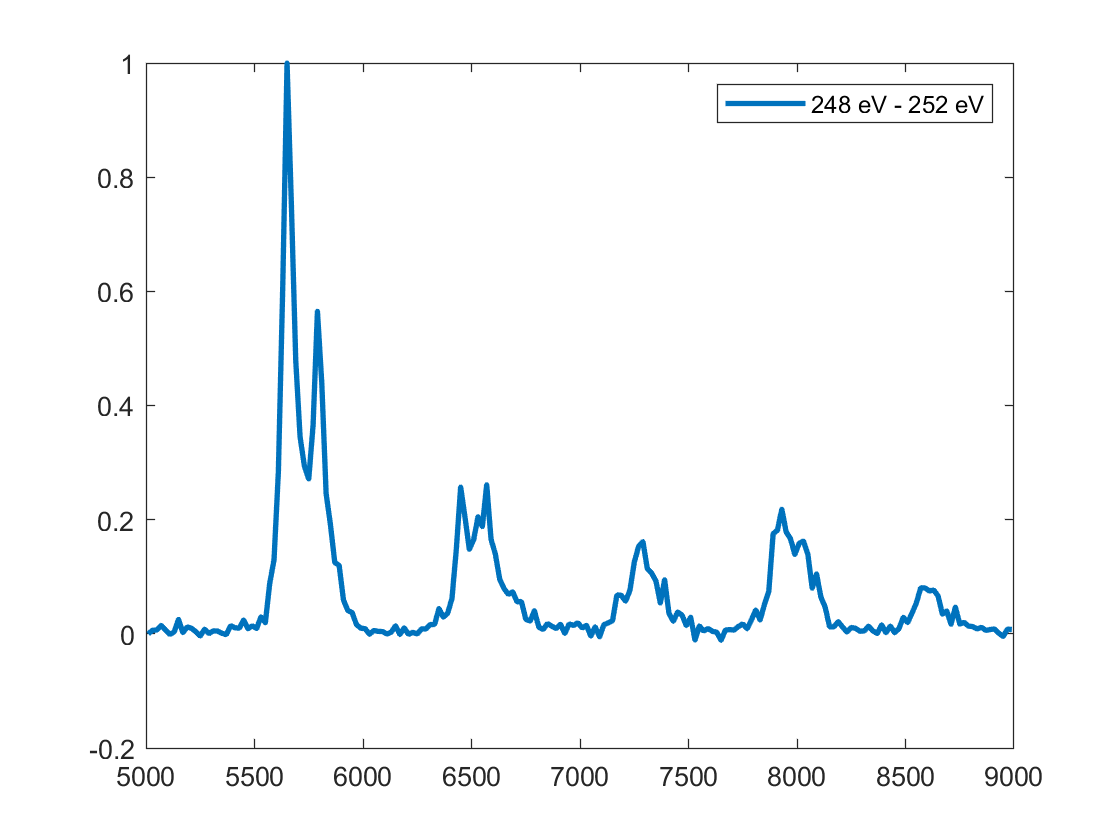

 figure
%  es_range = [245;248];
%  idx = Xcenters>es_range(1) & Xcenters<es_range(2);
%  tof = sum(TetEI_x_tof(idx,:));
%  label = sprintf('%.0f eV - %.0f eV', es_range(1),es_range(2));
%  plot(Ycenters,tof./max(tof), 'DisplayName',label, 'LineWidth',2)
%  hold on
%  legend
%  
 es_range = [248;252];
 idx = Xcenters>es_range(1) & Xcenters<es_range(2);
 tof = sum(TetEI_x_tof(idx,:));
  label = sprintf('%.0f eV - %.0f eV', es_range(1),es_range(2));
 plot(Ycenters,tof./max(tof), 'DisplayName',label,'LineWidth',2)
 legend

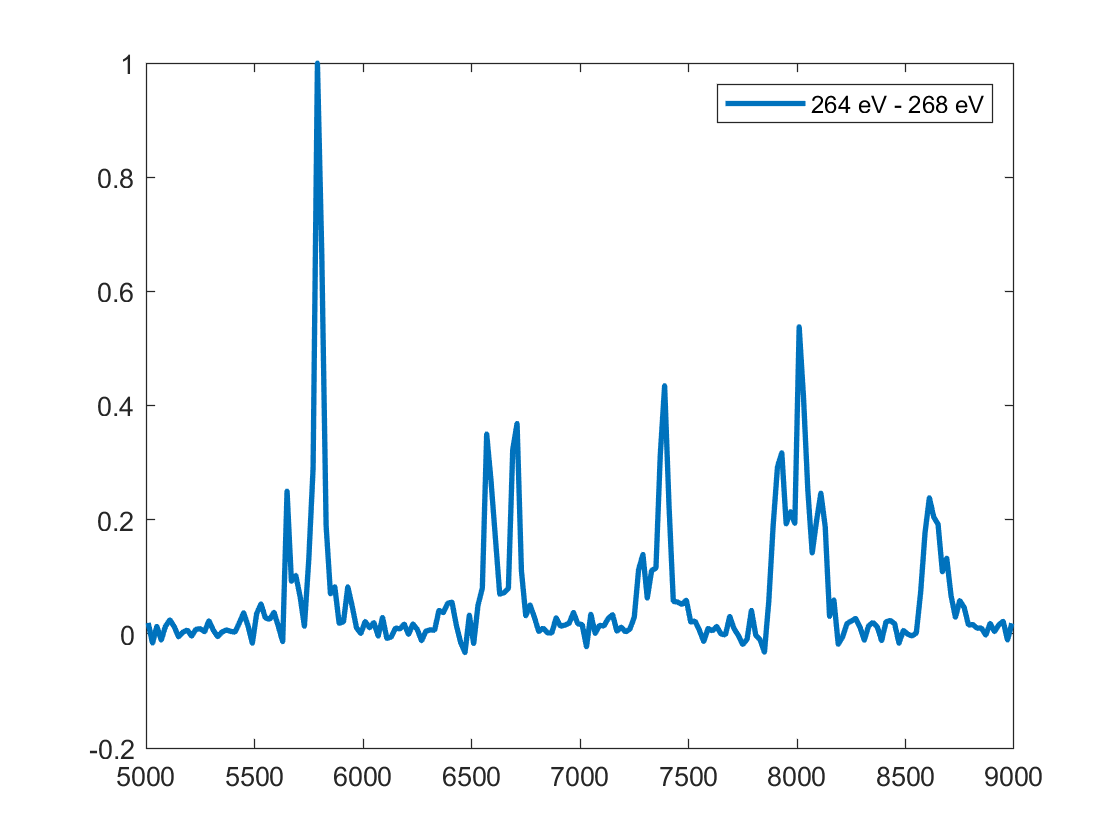

% 
%  es_range = [253;256];
%  idx = Xcenters>es_range(1) & Xcenters<es_range(2);
%  tof = sum(TetEI_x_tof(idx,:));
%  label = sprintf('%.0f eV - %.0f eV', es_range(1),es_range(2));
%  plot(Ycenters,tof./max(tof), 'DisplayName',label,'LineWidth',2)
% 
%  es_range = [258;262];
%  idx = Xcenters>es_range(1) & Xcenters<es_range(2);
%  tof = sum(TetEI_x_tof(idx,:));
%    label = sprintf('%.0f eV - %.0f eV', es_range(1),es_range(2));
%  plot(Ycenters,tof./max(tof), 'DisplayName',label,'LineWidth',2)
figure
 es_range = [264;268];
 idx = Xcenters>es_range(1) & Xcenters<es_range(2);
 tof = sum(TetEI_x_tof(idx,:));
   label = sprintf('%.0f eV - %.0f eV', es_range(1),es_range(2));
 plot(Ycenters,tof./max(tof), 'DisplayName',label,'LineWidth',2)
 legend